%APPENDIX A

%Close
CloseTimeArray = table2array(CloseTime);
CloseFrequencyArray = table2array(CloseFrequency);
%Med
MedFrequencyArray = table2array(MedFrequency);
MedTimeArray = table2array(MedTime);
%Far
FarFrequencyArray = table2array(FarFrequency);
FarTimeArray = table2array(FarTime);
%Time and Frequency Parameters
times_ns = 200:-.5:0 %in ns 

times_ns =   200.0000  199.5000  199.0000  198.5000  198.0000  197.5000  197.0000  196.5000  196.0000  195.5000  195.0000  194.5000  194.0000  193.5000  193.0000  192.5000  192.0000  191.5000  191.0000  190.5000  190.0000  189.5000  189.0000  188.5000  188.0000  187.5000  187.0000  186.5000  186.0000  185.5000  185.0000  184.5000  184.0000  183.5000  183.0000  182.5000  182.0000  181.5000  181.0000  180.5000  180.0000  179.5000  179.0000  178.5000  178.0000  177.5000  177.0000  176.5000  176.0000  175.5000


times_s = times_ns/(10^9) %in s

times_s = 	1.0e+-6 *

    0.2000    0.1995    0.1990    0.1985    0.1980    0.1975    0.1970    0.1965    0.1960    0.1955    0.1950    0.1945    0.1940    0.1935    0.1930    0.1925    0.1920    0.1915    0.1910    0.1905    0.1900    0.1895    0.1890    0.1885    0.1880    0.1875    0.1870    0.1865    0.1860    0.1855    0.1850    0.1845    0.1840    0.1835    0.1830    0.1825    0.1820    0.1815    0.1810    0.1805    0.1800    0.1795    0.1790    0.1785    0.1780    0.1775    0.1770    0.1765    0.1760    0.1755


freq_MHz = linspace(700, 1000, 401) %in MHz

freq_MHz = 	1.0e+03 *

    0.7000    0.7007    0.7015    0.7023    0.7030    0.7037    0.7045    0.7053    0.7060    0.7067    0.7075    0.7083    0.7090    0.7097    0.7105    0.7113    0.7120    0.7127    0.7135    0.7143    0.7150    0.7157    0.7165    0.7173    0.7180    0.7188    0.7195    0.7202    0.7210    0.7218    0.7225    0.7232    0.7240    0.7248    0.7255    0.7262    0.7270    0.7278    0.7285    0.7292    0.7300    0.7308    0.7315    0.7322    0.7330    0.7338    0.7345    0.7352    0.7360    0.7368


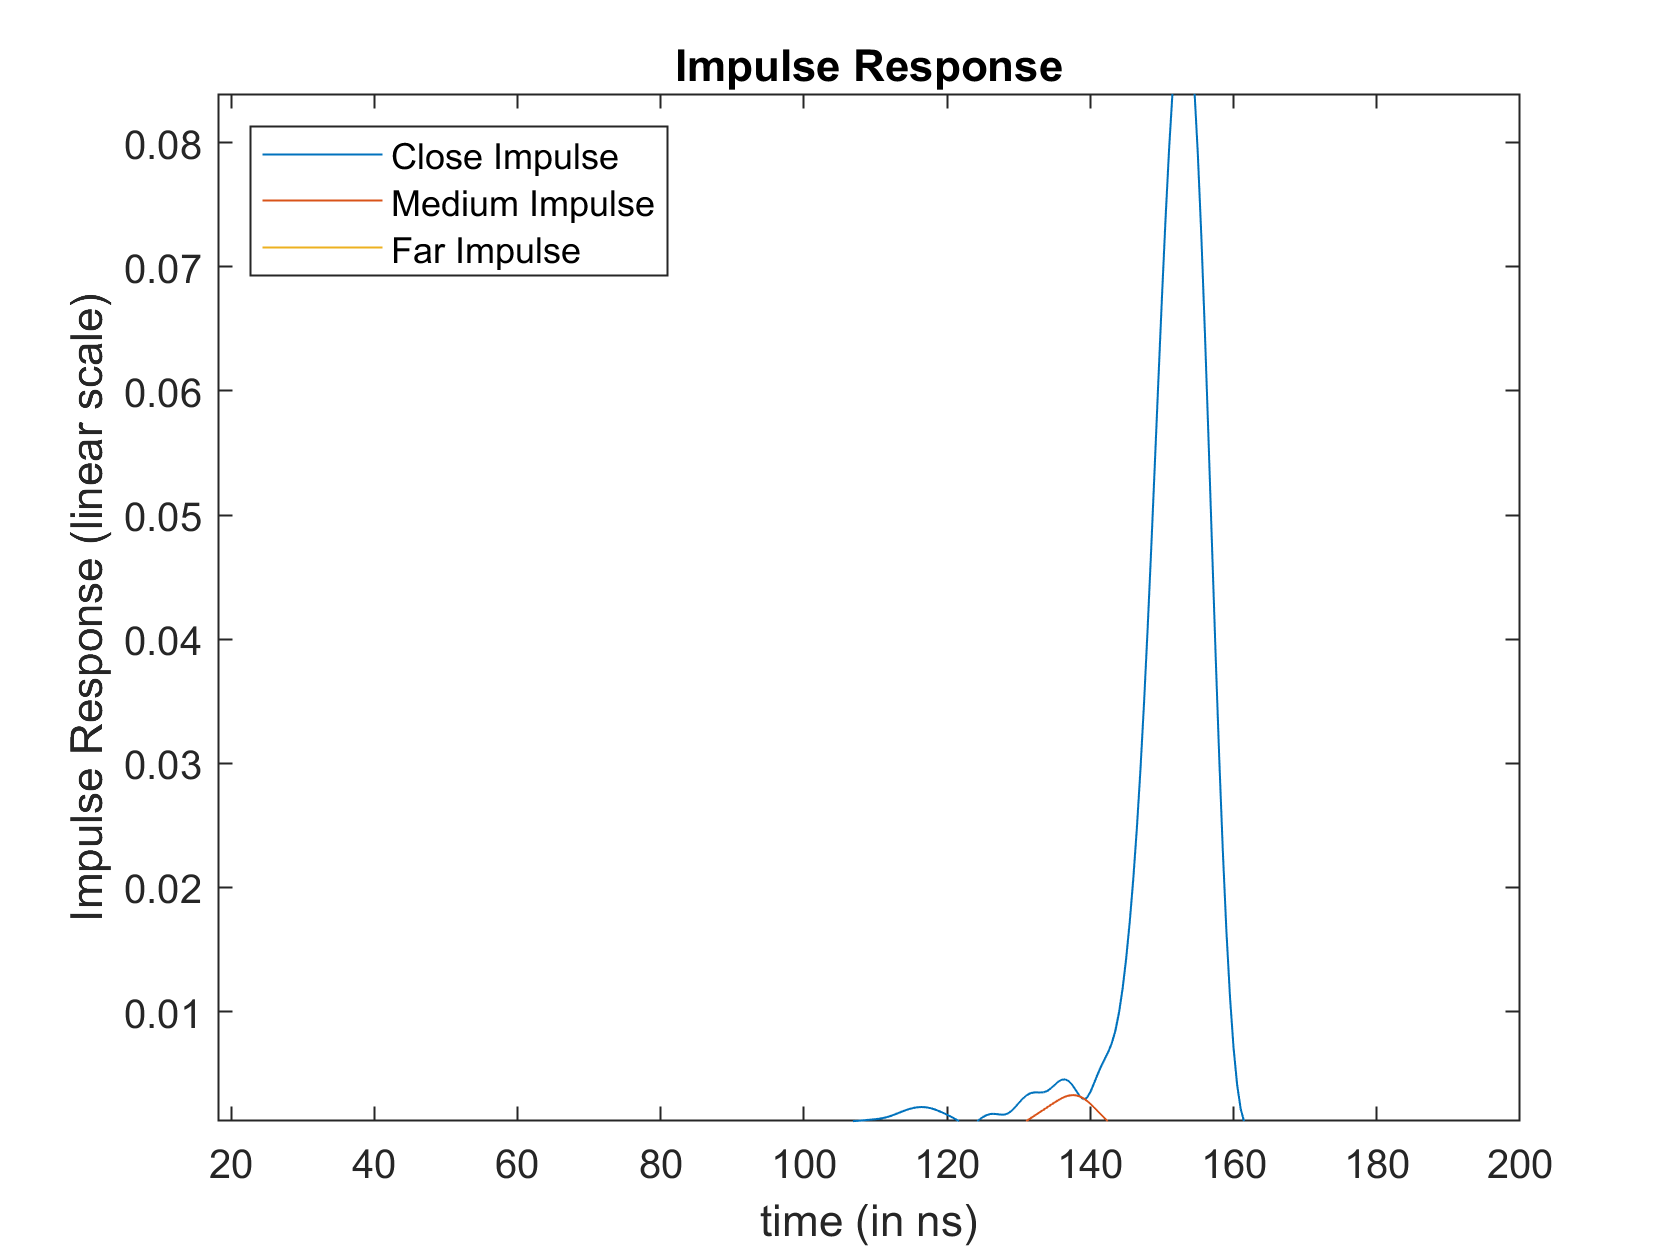

freq_Hz = freq_MHz/(10^-6); %in Hz 

%Plot Impulse Responses together
plot(times_ns, CloseTimeArray, times_ns, MedTimeArray, times_ns, FarTimeArray)
axis([0 200 0 .091])
title('Impulse Response')
xlabel('time (in ns)')
ylabel('Impulse Response (linear scale)')
legend({'Close Impulse', 'Medium Impulse', 'Far Impulse'},'Location','northwest')

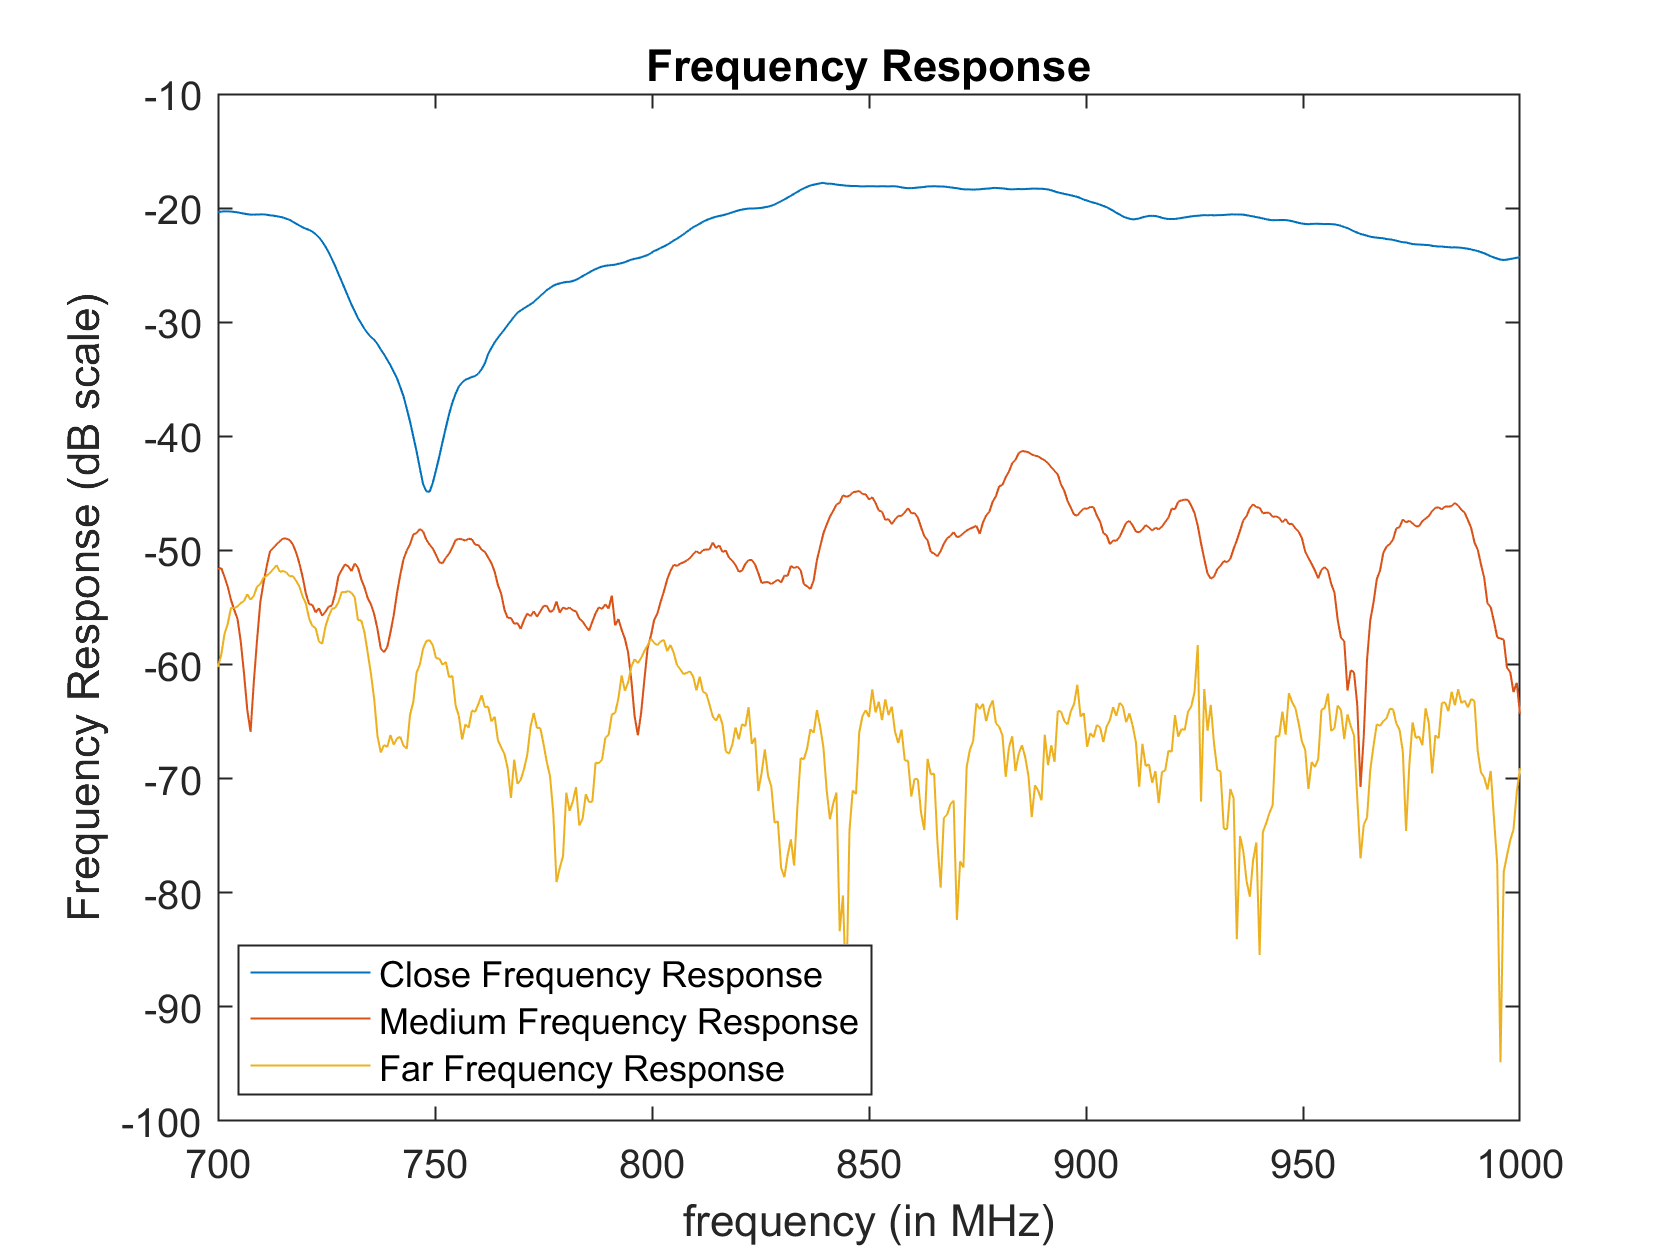


%Plot Frequency Responses Together
plot(freq_MHz, CloseFrequencyArray, freq_MHz, MedFrequencyArray, freq_MHz, FarFrequencyArray)
title('Frequency Response')
xlabel('frequency (in MHz)')
ylabel('Frequency Response (dB scale)')
legend({'Close Frequency Response', 'Medium Frequency Response', 'Far Frequency Response'},'Location','best')


%Close Calculations
%Calculate Close mean delay 
%mean_time = sum(CloseTimeArray.^2.*times_s)
num_brakt_close = 0;
num_tsqr_close = 0;
denom_close = 0; 
num_brakt_med = 0;
num_tsqr_med = 0;
denom_med = 0;
num_brakt_far = 0;
num_tsqr_far = 0;
denom_far = 0;
for i = 1:length(CloseTimeArray)
    %Close 
    num_brakt_close = num_brakt_close + (CloseTimeArray(i)^2)*times_s(i);
    num_tsqr_close = num_tsqr_close + (CloseTimeArray(i)^2)*(times_s(i)^2);
    denom_close = denom_close + (CloseTimeArray(i)^2);
    %Medium
    num_brakt_med = num_brakt_med + (MedTimeArray(i)^2*times_s(i));
    num_tsqr_med = num_tsqr_med + (MedTimeArray(i)^2)*(times_s(i)^2);
    denom_med = denom_med + (MedTimeArray(i)^2); 
    %Far
    num_brakt_far = num_brakt_far + (FarTimeArray(i)^2*times_s(i));
    num_tsqr_far = num_tsqr_far + (FarTimeArray(i)^2)*(times_s(i)^2);
    denom_far = denom_far + (FarTimeArray(i)^2);
end

%Mean Delay (first and second moments)
%Close 
brakt_close = num_brakt_close/denom_close %this is mean delay, in s

brakt_close = 1.5258e-07

tsqr_close = num_tsqr_close/denom_close %this is the second moment, in s

tsqr_close = 2.3291e-14

%Medium
brakt_med = num_brakt_med/denom_med

brakt_med = 1.3208e-07

tsqr_med = num_tsqr_med/denom_med

tsqr_med = 1.7643e-14

%Far
brakt_far = num_brakt_far/denom_far

brakt_far = 8.8339e-08

tsqr_far = num_tsqr_far/denom_far

tsqr_far = 8.3505e-15


%Calculate RMS delay spread
%Close
sigmah_close = sqrt(tsqr_close-(brakt_close)^2) %in s

sigmah_close = 3.2412e-09

%Medium
sigmah_med = sqrt(tsqr_med - (brakt_med)^2)

sigmah_med = 1.4059e-08

%Far
sigmah_far = sqrt(tsqr_far - (brakt_far)^2)

sigmah_far = 2.3384e-08


%Calculate coherance bandwidth
%Bc = 1/5sigmah
Bc_close = (5*sigmah_close)^-1

Bc_close = 6.1705e+07

Bc_med = (5*sigmah_med)^-1

Bc_med = 1.4225e+07

Bc_far = (5*sigmah_far)^-1

Bc_far = 8.5528e+06